# Comparison between time-domain and frequency-domain approaches

## Introduction

The lateral, vertical and torsional response of a suspension is computed in the time domain using computed turbulent velocity time histories. The simplified Bridge model of the Lysefjord Bridge [1] is considered for the modelling of the structure. Turbulence is modelled using the Kaimal model [2]. The quasi-steady theory, as well as the strip assumption, are used. Modal coupling between the lateral, vertical and torsional motions are accounted for in the time-domain model with the function **dynaRespTD**. On the other hand, the function **dynaRespTD_noCoupling **computes the time histories of the bridge response without modal coupling and using a linearised wind load.  Similarily, the frequency domain approach used hereafter with the function **dynaRespFD** does not account for any modal coupling or non-linearity of the wind load. 

N.B.: A low number of modes and nodes is used to reduce the computation time.

#### References

[1] Cheynet, E., Jakobsen, J. B., & Snæbjörnsson, J. (2016). Buffeting response of a suspension bridge in complex terrain. *Engineering Structures*, *128*, 474-487.

[2] Kaimal, J. C., Wyngaard, J. C. J., Izumi, Y., & Coté, O. R. (1972). Spectral characteristics of surface‐layer turbulence. *Quarterly Journal of the Royal Meteorological Society*, *98*(417), 563-589.

## Parameters definitions

### Time and sampling frequency

clearvars;close all;clc;
fs = 18; % sampling frequency (in Hertz)
M = 14; % M is the power of 2: 2^M 
[t,f] = getSamplingPara(M,fs); % get time and frequency vector

Duration of target time series is 0.253 hours, i.e. 910 sec 



N=numel(t); % number of time step (should be equal to 2^M)
Nfreq = numel(f); % number of frequency step (should be equal to 2^(M-1))
dt = median(diff(t)); % time step (should be equal to 1/fs)

### Bridge parameters definition

The function eigenBridge has been introduced in the following Matlab File Exchange submission: [https://se.mathworks.com/matlabcentral/fileexchange/51815-calculation-of-the-modal-parameters-of-a-suspension-bridge](https://se.mathworks.com/matlabcentral/fileexchange/51815-calculation-of-the-modal-parameters-of-a-suspension-bridge) 

Nzz = 1; % A horizontal bridge is used, so no need to have multiple nodes in the vertical direction
Nyy = 40; % Number of node for the line-like structure 
Nmodes = 4; % Number of modes for the bridge
[Bridge] = LysefjordBridge(Nyy); % Case of the Lysefjord Bridge (simplified model)

[wn,phi] = eigenBridge(Bridge,Nmodes); % Get the mode shapes and eigenfrequencies
zetaStruct = [5e-3*ones(3,Nmodes)]; % Structural damping

% Complete the variable Bridge with wn, phi and zetaStruct
Bridge.zetaStruct= zetaStruct;
Bridge.wn = wn;
Bridge.phi = phi;

### Wind parameters definition

The turbulence is generated using the following Matlab File Exchange submission: [https://se.mathworks.com/matlabcentral/fileexchange/68632-wind-field-simulation-the-fast-version](https://se.mathworks.com/matlabcentral/fileexchange/68632-wind-field-simulation-the-fast-version) 

kappa = 0.40; % von karman constant
zref = 55; % reference height
z0 = 0.05; % roughness height
Uref = [10:2:30]; % reference wind speed

[Y,Z] = meshgrid(Bridge.y.*Bridge.L,zref);

% Coherence parameters (Davenport model)
clear CoeffDecay
CohDecay.Cuy = 7; % Arbitrary decay coefficient for u in the "y" direction
CohDecay.Cuz = 10; % Arbitrary decay coefficient for u in the "z" direction
CohDecay.Cvy = 7; % Arbitrary decay coefficient for v in the "y" direction
CohDecay.Cvz = 10; % Arbitrary decay coefficient for v in the "z" direction
CohDecay.Cwy = 6.5; % Arbitrary decay coefficient for w in the "y" direction
CohDecay.Cwz = 3; % Arbitrary decay coefficient for w in the "z" direction

Nm = Nzz*Nyy;
M = numel(Uref);


[~,indStart] = min(abs(t-200)); % Remove the first 200 sec (transient response)
[~,indR] = min(abs(Bridge.y-0.5)); % Get response at midspan
stdRespDispl  = nan(3,M); % STD of the displacement response
stdRespAcc  = nan(3,M); % STD of the acceleration response

stdAox  = nan(1,M); % STD of the lateral acceleration response (linear laod + uncoupled modal response)
stdAoz  = nan(1,M); % STD of the lateral acceleration response (linear laod + uncoupled modal response)
stdAot  = nan(1,M); % STD of the lateral acceleration response (linear laod + uncoupled modal response)

rng(10)


for oo=1:M
    
    u_star =  kappa*Uref(oo)./log(zref/z0); % The logarithmic mean wind profile is adopted. 
    % The friction velocity u_star is computed using zref (reference
    % height) and Uref (reference mean wind speed). The friciton velocity
    % is assumed constant with height in the present example.
    U = u_star./kappa.*log(Z./z0);
    
    % Get the target velocity spectral densities (Kaimal model)
    Su = zeros(Nm,Nfreq);
    Sv = zeros(Nm,Nfreq);
    Sw = zeros(Nm,Nfreq);
    Svw = zeros(Nm,Nfreq);
    Suw = zeros(Nm,Nfreq);
    for jj=1:Nm
        fr = (f*Z(jj)/U(jj));
        Su(jj,:) = 102.*fr./(1+33.*fr).^(5/3).*u_star.^2./f; % Kaimal  model (NOT normalized)
        Sv(jj,:) = 17.*fr./(1+9.5.*fr).^(5/3).*u_star.^2./f; % Kaimal  model (NOT normalized)
        Sw(jj,:) = (2.*fr./(1+5.*fr.^(5/3))).*u_star.^2./f; % Kaimal model (NOT normalized)
        Suw(jj,:) = -14.*fr./(1+10.5*fr).^(7/3).*u_star.^2./f; % Kaimal cross-spectrum model (NOT normalized)
    end
    
    tic
     % Call the function windSimFast
    [u,v,w,nodes] = windSimFast(U,f,Su,Sv,Sw,CohDecay,Y,Z,'Suw',Suw); %  Suw is here an option!
    u = bsxfun(@plus,u,U(:)');
    u = squeeze(reshape(u,N,Nzz,Nyy)); % whos u1
    w = squeeze(reshape(w,N,Nzz,Nyy));% whos w1

    % Compute the Bridge response with the function dynaRespTD (coupled
    % modal response + nonlinear load) and dynarRespTD_noCoupling
    [Do] = dynaRespTD(Bridge,u,w,t);
    % Compute the lateral bridge response (linear load + uncoupled)
    [Dox] = dynaRespTD_noCoupling(Bridge,u,w,t,'lateral');

    
%     [S2,f2]=pwelch(detrend(Dox(20,:)),[],[],[],fs);
%     [S1,f1]=pwelch(detrend(squeeze(Do(1,20,:))),[],[],[],fs);
%     loglog(f1,S1,f2,S2);legend('coupled','uncoupled','FD')



    % Compute the vertical bridge response (linear load + uncoupled)
    [Doz] = dynaRespTD_noCoupling(Bridge,u,w,t,'vertical');
    
     % Compute the torsional bridge response (linear load + uncoupled)
    [Dot] = dynaRespTD_noCoupling(Bridge,u,w,t,'torsional');

    
    toc
    
    
    % Get the acceleration response
    Ao = diff(Do,2,3)./dt.^2;
    Aox = diff(Dox,2,2)./dt.^2;
    Aoz = diff(Doz,2,2)./dt.^2;
    Aot = diff(Dot,2,2)./dt.^2;
    % Compute the Root-mean square (RMS) of the response
    for jj=1:3
        stdRespDispl(jj,oo) = std(detrend(squeeze(Do(jj,indR,indStart:end))));
        stdRespAcc(jj,oo) = std(detrend(squeeze(Ao(jj,indR,indStart:end))));
    end
    
    stdAox(oo) = std(detrend(Aox(indR,indStart:end)));
    stdAoz(oo) = std(detrend(Aoz(indR,indStart:end)));
    stdAot(oo) = std(detrend(Aot(indR,indStart:end)));
    
end

Elapsed time is 24.399734 seconds.
Elapsed time is 24.816667 seconds.
Elapsed time is 24.664857 seconds.
Elapsed time is 23.987790 seconds.
Elapsed time is 23.366493 seconds.
Elapsed time is 28.254794 seconds.
Elapsed time is 28.939559 seconds.
Elapsed time is 27.271899 seconds.
Elapsed time is 25.616419 seconds.
Elapsed time is 24.893832 seconds.
Elapsed time is 27.816499 seconds.


## Computation of the bridge response in the frequency domain

For comparison purpose, the bridge response is also computed in the frequency domain using the following Matlab File Exchange submission: [https://se.mathworks.com/matlabcentral/fileexchange/51970-buffeting-response-of-a-suspension-bridge-frequency-domain](https://se.mathworks.com/matlabcentral/fileexchange/51970-buffeting-response-of-a-suspension-bridge-frequency-domain) 

Note that the frequency domain approach is used here without modal coupling, while the function dynaRespTD account for coupling terms between the lateral, vertical and torsional degrees of freedom.

Nfreq2= 1500; % For computational efficiency, a new frequency vector is defined here
f_FD = logspace(log10(f(1)),log10(f(end)),Nfreq2);
d = Bridge.y.*Bridge.L;

Srx = nan(M,Nfreq2);
Srz = nan(M,Nfreq2);
Srt = nan(M,Nfreq2);
BridgeFD = Bridge;

for oo=1:M
    tic
    u_star =  kappa*Uref(oo)./log(zref/z0); % The logarithmic mean wind profile is adopted
    U = u_star./kappa.*log(Z./z0);
    Su = zeros(Nm,Nfreq2);
    Sv = zeros(Nm,Nfreq2);
    Sw = zeros(Nm,Nfreq2);
    Svw = zeros(Nm,Nfreq2);
    Suw = zeros(Nm,Nfreq2);
    for jj=1:Nm
        fr = (f_FD*Z(jj)/U(jj));
        Su(jj,:) = 102.*fr./(1+33.*fr).^(5/3).*u_star.^2./f_FD; % Kaimal  model (NOT normalized)
        Sv(jj,:) = 17.*fr./(1+9.5.*fr).^(5/3).*u_star.^2./f_FD; % Kaimal  model (NOT normalized)
        Sw(jj,:) = (2.*fr./(1+5.*fr.^(5/3))).*u_star.^2./f_FD; % Kaimal model (NOT normalized)
        Suw(jj,:) = -14.*fr./(1+10.5*fr).^(7/3).*0.75.^2./f_FD; % Kaimal cross-spectrum model (NOT normalized)
    end
    
    Wind.U =U(1); 
    Wind.Su =  Su(1,:); % All the Su values are the same in the dimension 1 as the bridge is horizontal
    Wind.Sw =  Sv(1,:);
    Wind.Suw = Suw(1,:);
    Wind.Cuy = CohDecay.Cuy;
    Wind.Cwy = CohDecay.Cwy;
    Wind.f = f_FD;
    
    
    % Compute the lateral bridge response
    BridgeFD.DOF = 'lateral';
    BridgeFD.phi = squeeze(Bridge.phi(1,:,:));
    BridgeFD.wn = Bridge.wn(1,:);
    BridgeFD.zetaStruct = Bridge.zetaStruct(1,:,:);
    [Srx(oo,:)] = dynaRespFD(BridgeFD,Wind,indR);
    
    % Compute the vertical bridge response
    BridgeFD.DOF = 'vertical';
    BridgeFD.phi = squeeze(Bridge.phi(2,:,:));
    BridgeFD.wn = Bridge.wn(2,:);
    BridgeFD.zetaStruct = Bridge.zetaStruct(2,:,:);
    [Srz(oo,:)] = dynaRespFD(BridgeFD,Wind,indR);
    
    % Compute the torsional bridge response
    BridgeFD.DOF = 'torsional';
    BridgeFD.phi = squeeze(Bridge.phi(3,:,:));
    BridgeFD.wn = Bridge.wn(3,:);
    BridgeFD.zetaStruct = Bridge.zetaStruct(3,:,:);
    [Srt(oo,:)] = dynaRespFD(BridgeFD,Wind,indR);
    
    
    toc
end

Elapsed time is 2.370059 seconds.
Elapsed time is 2.066229 seconds.
Elapsed time is 1.994871 seconds.
Elapsed time is 2.119231 seconds.
Elapsed time is 1.640819 seconds.
Elapsed time is 1.594746 seconds.
Elapsed time is 1.525937 seconds.
Elapsed time is 1.557041 seconds.
Elapsed time is 1.807832 seconds.
Elapsed time is 1.786153 seconds.
Elapsed time is 1.586358 seconds.




% RMS of acceleration response
stdAxFD= sqrt(trapz(f_FD,Srx.*(2*pi*f_FD).^4,2));
stdAzFD= sqrt(trapz(f_FD,Srz.*(2*pi*f_FD).^4,2));
stdAtFD= sqrt(trapz(f_FD,Srt.*(2*pi*f_FD).^4,2));
% 
% stdRxFD= sqrt(trapz(f2,Srx,2));
% stdRzFD= sqrt(trapz(f2,Srz,2));
% stdRtFD= sqrt(trapz(f2,Srt,2));

## Results

### Time series visualization

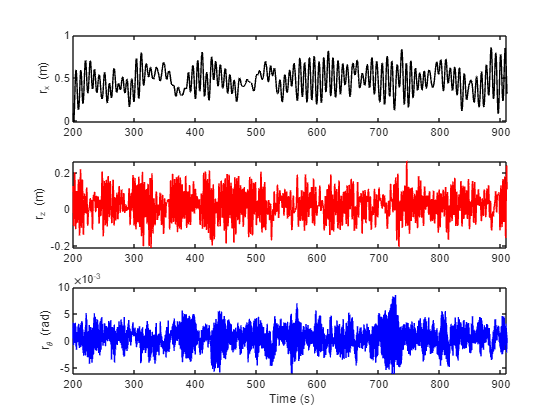


rx = squeeze(Do(1,indR,indStart:end));
rz = squeeze(Do(2,indR,indStart:end));
rt = squeeze(Do(3,indR,indStart:end));

clf;close all;
figure
subplot(311)
plot(t(indStart:end),rx,'k');
ylabel('r_x (m)')
xlim([t(indStart),t(end)])

subplot(312)
plot(t(indStart:end),rz,'r');
ylabel('r_z (m)')
xlim([t(indStart),t(end)])

subplot(313)
plot(t(indStart:end),rt,'b');
ylabel('r_\theta (rad)')
xlabel(' Time (s)')
xlim([t(indStart),t(end)])

set(gcf,'color','w')

### PSD visualization

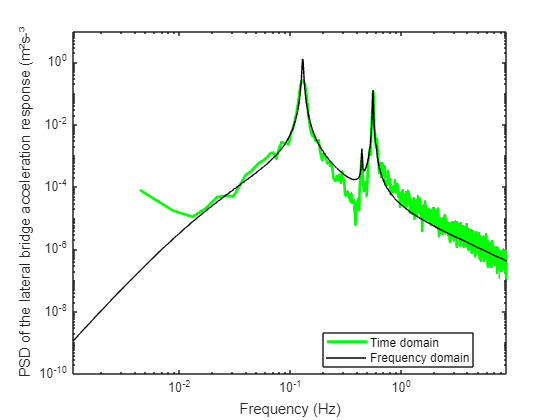

ind_FD = M;
ax = detrend(diff(Dox(indR,indStart:end),2)./dt.^2);
az = detrend(diff(Doz(indR,indStart:end),2)./dt.^2);
at = detrend(diff(Dot(indR,indStart:end),2)./dt.^2);


[Srx_TD,fx] = pwelch(ax,[],[],[],fs);
[Srz_TD,fz] = pwelch(az,[],[],[],fs);
[Srt_TD,ft] = pwelch(at,[],[],[],fs);

clf;close all;
figure
loglog(fx,Srx_TD,'g','linewidth',2);
hold on
loglog(f_FD,Srx(M,:).*(2*pi*f_FD).^4,'k');
legend('Time domain','Frequency domain','location','best')
axis tight
set(gcf,'color','w')
xlabel('Frequency (Hz)')
ylabel('PSD of the lateral bridge acceleration response (m²s-³')
ylim([1e-10,10])

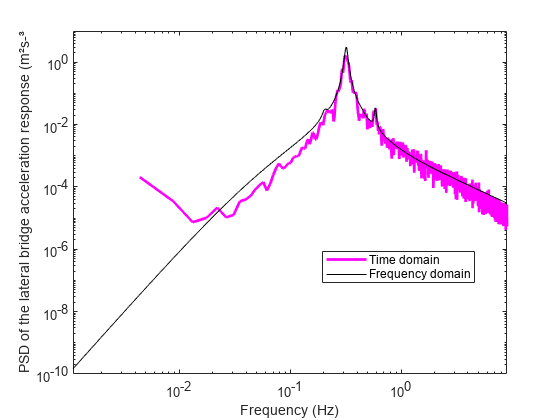


figure
loglog(fz,Srz_TD,'m','linewidth',2);
axis tight
hold on
loglog(f_FD,Srz(M,:).*(2*pi*f_FD).^4,'k');
xlabel('Frequency (Hz)')
legend('Time domain','Frequency domain','location','best')
set(gcf,'color','w')
ylim([1e-10,10])
ylabel('PSD of the lateral bridge acceleration response (m²s-³')

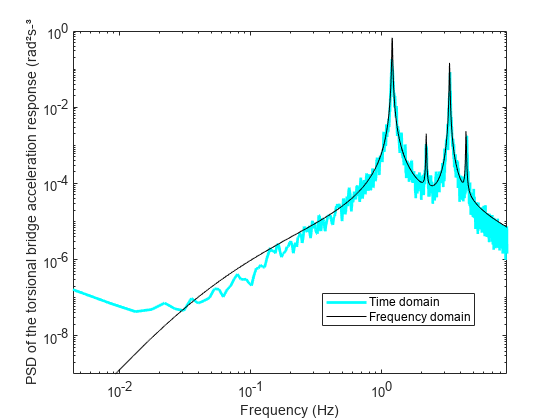


figure
loglog(ft,Srt_TD,'c','linewidth',2);
hold on
loglog(f_FD,Srt(M,:).*(2*pi*f_FD).^4,'k');
legend('Time domain','Frequency domain','location','best')
axis tight
set(gcf,'color','w')
ylim([1e-9,1])
xlabel('Frequency (Hz)')
ylabel('PSD of the torsional bridge acceleration response (rad²s-³')

### RMS of the response

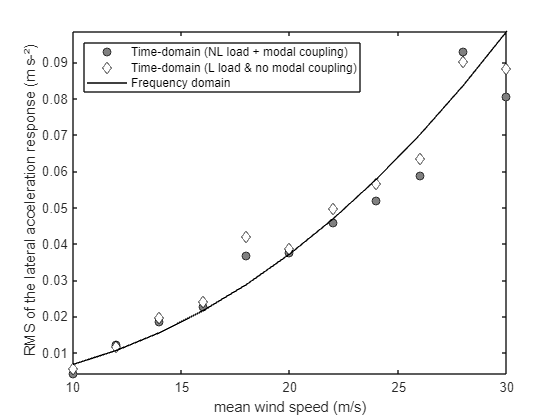


clf;close all;
figure
plot(Uref,stdRespAcc(1,:),'ko','markerfacecolor',[0.5,0.5,0.5]);
hold on
plot(Uref,stdAox,'kd','markerfacecolor','w');
plot(Uref,stdAxFD,'k')
legend('Time-domain (NL load + modal coupling)','Time-domain (L load & no modal coupling)','Frequency domain','location','northWest');
xlabel('mean wind speed (m/s)')
axis tight
set(gcf,'color','w')
ylabel(' RMS of the lateral acceleration response (m s-²)')

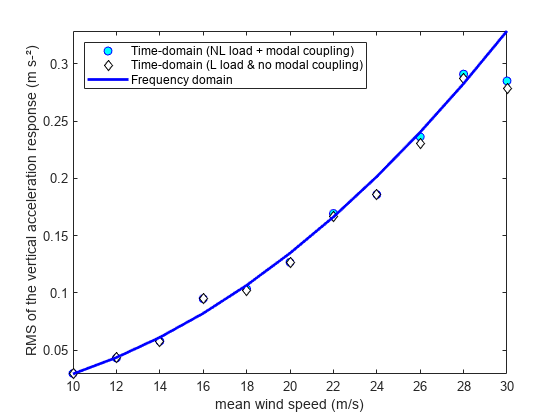


figure
plot(Uref,stdRespAcc(2,:),'bo','markerfacecolor','c');
hold on
plot(Uref,stdAoz,'kd','markerfacecolor','w');
plot(Uref,stdAzFD,'b','linewidth',2)
axis tight
set(gcf,'color','w')
legend('Time-domain (NL load + modal coupling)','Time-domain (L load & no modal coupling)','Frequency domain','location','northWest');
xlabel('mean wind speed (m/s)')
ylabel(' RMS of the vertical acceleration response (m s-²)')

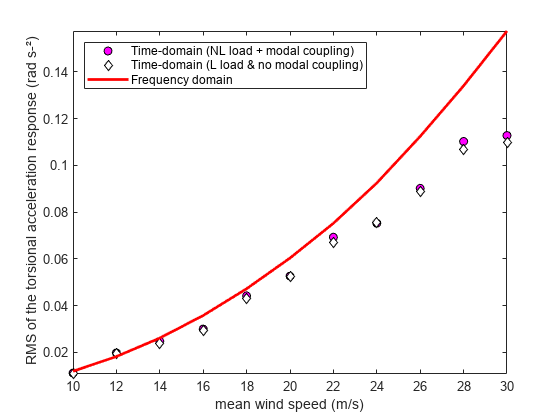


figure
plot(Uref,stdRespAcc(3,:),'ko','markerfacecolor','m');
hold on
plot(Uref,stdAot,'kd','markerfacecolor','w');
plot(Uref,stdAtFD,'r','linewidth',2)
axis tight
set(gcf,'color','w')
legend('Time-domain (NL load + modal coupling)','Time-domain (L load & no modal coupling)','Frequency domain','location','northWest');
xlabel('mean wind speed (m/s)')
ylabel(' RMS of the torsional acceleration response (rad s-²)')